**The For Loop**

for i = 1:5
    fprintf('%d\n', i)
end

1
2
3
4
5


disp([1:5]')

     1
     2
     3
     4
     5



disp([1:5])

     1     2     3     4     5



for i = 0:50:200
    fprintf('%d\n', i)
end

0
50
100
150
200


for i = 0:50:200
    fprintf('%3d\n', i)
end

  0
 50
100
150
200


for i = 1:5
    fprintf('*\n')
end

*
*
*
*
*


repelem('*', 10)'

ans = 10×1 char array
    '*'
    '*'
    '*'
    '*'
    '*'
    '*'
    '*'
    '*'
    '*'
    '*'


**Preallocation a Vector**

n = randi([4 8]);
vec = zeros(1, n);

for i = 1:n
    theNumber = input('Enter a number: ');
    vec(i) = theNumber;
end 

fprintf('The vector is: \n')

The vector is: 


disp(vec)

    23    14   189    39



**Subplot(r, c, n) = a subplot matrix, starting numbering rowise in upper left corner (r = numrows, c = numcols of plots in the window)**

y =          0    0.3247    0.6142    0.8372    0.9694    0.9966    0.9158    0.7357    0.4759    0.1646   -0.1646   -0.4759   -0.7357   -0.9158   -0.9966   -0.9694   -0.8372   -0.6142   -0.3247   -0.0000


y =          0    0.1604    0.3167    0.4647    0.6007    0.7212    0.8230    0.9035    0.9605    0.9927    0.9992    0.9798    0.9350    0.8660    0.7746    0.6631    0.5345    0.3920    0.2393    0.0805   -0.0805   -0.2393   -0.3920   -0.5345   -0.6631   -0.7746   -0.8660   -0.9350   -0.9798   -0.9992   -0.9927   -0.9605   -0.9035   -0.8230   -0.7212   -0.6007   -0.4647   -0.3167   -0.1604   -0.0000


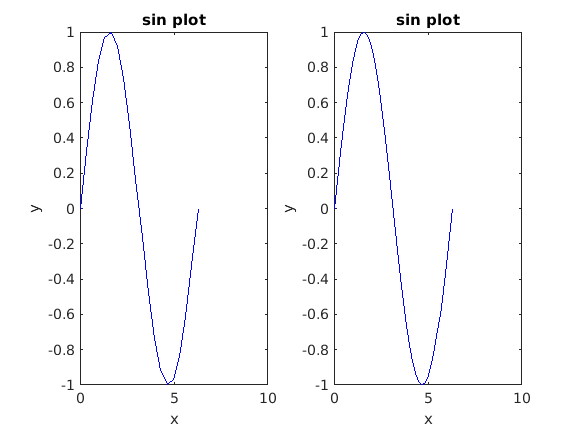


for i = 1:2
    x = linspace(0, 2*pi, 20*i);
    y = sin(x)
    
    % making the particular ith plot active so we can
    % use the plotting functions and make the plot
    % inside this ith window. 
    subplot(1, 2, i)
    % note - 1-2 never changes, same as i-range. 
    
    
    plot(x, y, 'b-')
    xlabel('x')
    ylabel('y')
    title('sin plot')
end 

**Nested For Loops**

% prints a box of stars
rows = 3;
columns = 5;

% loop over rows
for i = 1:rows
    %for every row loop to print *'s and then one \n
    for j = 1:columns
        fprintf('*')
    end
    fprintf('\n')
end

*****

*****

*****

% prints a triangle (along the wall)

rows = 3;
for i = 1:rows
    % inner loop
    for j = 1:i
        fprintf('*')
    end 
    fprintf('\n')
end 

******

% Create a multiplication table
multTable(4, 5)

ans =      1     2     3     4     5
     2     4     6     8    10
     3     6     9    12    15
     4     8    12    16    20


multTable(1,1)

ans = 1

multTable(2,8)

ans =      1     2     3     4     5     6     7     8
     2     4     6     8    10    12    14    16



createMultTable

ans =      1     2     3     4
     2     4     6     8
     3     6     9    12
     4     8    12    16
     5    10    15    20


load myMultTable.dat
who


Your variables are:

ans          i            j            n            radius       runProd      theNumber    vec          y            
columns      inputNum     myMultTable  num          rows         str          v            x            



myMultTable

myMultTable =      1     2     3     4
     2     4     6     8
     3     6     9    12
     4     8    12    16
     5    10    15    20


**Printing Rowwise Sum (pos only) from matrix**

dataVals = [33 -11 2; 4 5 9; 22 5 -7; 2 11 3]

dataVals =     33   -11     2
     4     5     9
    22     5    -7
     2    11     3



[r c] = size(dataVals);

for row = 1:r
    runSum = 0;
    for col = 1:c
        if dataVals(row, col) >= 0
            runSum = runSum + dataVals(row, col);
        end
    end
    fprintf('The sum for row %d is %d\n', row, runSum)
end

The sum for row 1 is 35
The sum for row 2 is 18
The sum for row 3 is 27
The sum for row 4 is 16


**Printing Colwise Sum (pos only) from matrix**

dataVals = [33 -11 2; 4 5 9; 22 5 -7; 2 11 3]

dataVals =     33   -11     2
     4     5     9
    22     5    -7
     2    11     3



[r c] = size(dataVals);

for col = 1:c
    runSum = 0;
    for row = 1:r
        if dataVals(row, col) >= 0
            runSum = runSum + dataVals(row, col);
        end
    end
    fprintf('The sum for col %d is %d\n', col, runSum)
end

The sum for col 1 is 61
The sum for col 2 is 21
The sum for col 3 is 14


**Summing Rows (positives) Vectorized:**


dataVals2 = dataVals
negIndices = dataVals2 < 0
dataVals2(negIndices) = NaN 

dataVals2 =     33   -11     2
     4     5     9
    22     5    -7
     2    11     3


negIndices = 4×3 logical array
   0   1   0
   0   0   0
   0   0   1
   0   0   0


for row = 1:r

dataVals2 =     33   NaN     2
     4     5     9
    22     5   NaN
     2    11     3


    fprintf(['The sum for row %d is ' ...
        '%d\n'], row, sum(dataVals2(row, :), 'omitnan'))
end

The sum for row 1 is 35
The sum for row 2 is 18
The sum for row 3 is 27
The sum for row 4 is 16


**While Loops**

factorialWhileLoop(10)

ans = 3628800

factorialWhileLoop(7)

ans = 5040

factorialWhileLoop(1)

ans = 1

factorialWhileLoop(0)

ans = 1

**Inefficient method of getting data using sentinel: **

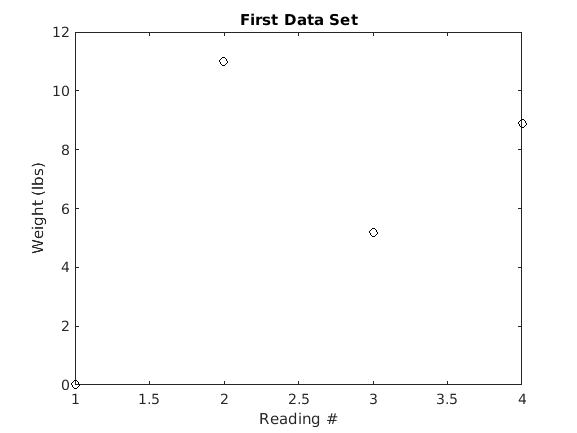

% Plots data up to -99 in a file

load experData.dat
i = i;
while experData(i) ~= -99
    newVec(i) = experData(i);
    i = i + 1;
end

subplot(1,1,1)
plot(newVec, 'ko')
xlabel('Reading #')
ylabel('Weight (lbs)')
title('First Data Set')

**Efficient Method**

clear

load experData.dat

where = find(experData == -99);
newVec = experData(1:where-1) %prealloc

newVec =     3.1000   11.0000    5.2000    8.9000


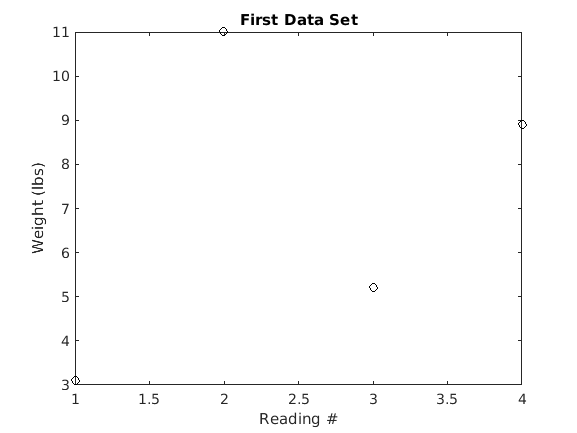


plot(newVec, 'ko')
xlabel('Reading #')
ylabel('Weight (lbs)')
title('First Data Set')

% input until negative
% if char, error will be thrown in the command line
% (but not in the live script)
inp = input('Enter a positive number: ');
while inp >= 0
    fprintf('You entered a %d.\n\n', inp)
    inp = input('Enter a positive number: ');
end

You entered a 23.

You entered a 23.

You entered a 12.

You entered a 116.



fprintf('OK!\n')

OK!


**Methods of Extending a Vector (Avoid, is inefficient): **

**Method 1: **

vec = [];
inp = input('Enter the number: ');
while inp >= 0
    vec = [vec inp];
    inp = input('Enter another one: ');
end

vec

vec =      4    23    55    78


clear

i = 0; 
inp = input('Enter the number: ');
while inp >= 0
    i = i + 1;
    % NOTE  - this is created right here
    % and accessible outside the while loop!
    newVec(i) = inp; 
    inp = input('Enter a new one: ');
end

newVec 

newVec =    234     5


% Reading until positive num: 
ReadUntilPos

Thanks you entered a 34.0 


% Getting the signs of a matrix using For loop
mat = [0 4 -3; -1 0 2];

signNumMat(mat)

ans =      0     1    -1
    -1     0     1


sign(mat) % using vectorized method

ans =      0     1    -1
    -1     0     1



% Getting the min of a vec using for loop
vec = [1 89 3 4 -45 0 1];
minVec(vec)

theMin = -45

ans = -45

min(vec) % vectorized

ans = -45

% Can check code with this: (if no output, all's good)
checkcode('minVec')
checkcode('ReadUntilPos')

% OR
% Click on down arrow of Current Folder ->
% Reports -> Code Analyzer Report to get code analysis.
